# Quickstart of **SaivDr Package**

A brief introduction to image restroation with **SaivDr Package**

## Summary

**SaivDr** is an abbreviation of *Sparsity-Aware Image and Volume Data Restoration*. This package is developed for

- Experiments, 

- Development and 

- Implementation

of sparsity-aware image and volume data restoraition algorithms.

In particular, this package provides a rich set of classes related to  [non-separable oversampled lapped transform ( **NSOLTs** )](https://sigport.org/documents/multidimensional-nonseparable-oversampled-lapped-transforms-theory-and-design) , which allows for convolutional layers with

- Parseval tight (paraunitary),

- Symmetric and

- Multiresolution 

properties. For some features, we have prepared custom layer classes for Deep Learning Toolbox. It is now easy to incorporate them into flexible configurations and parts of your network.

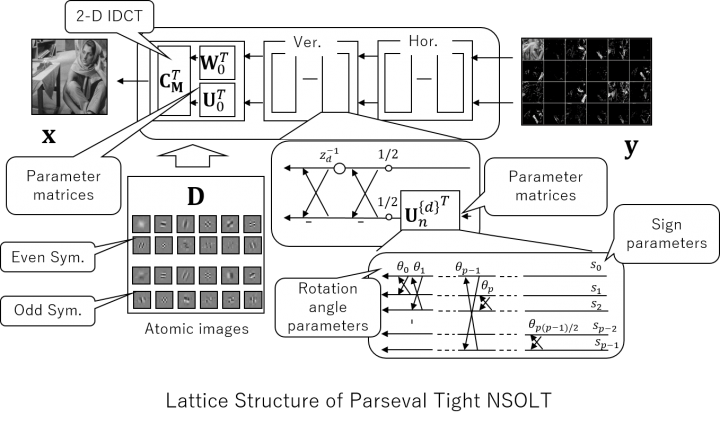

Information about **SaivDr Package** is given in Contents.m. The HELP command can be used to see the contents as follows:

type README.md

# SaivDr Package for MATLAB/Simulink [![View SaivDr Package on File Exchange](https://www.mathworks.com/matlabcentral/images/matlab-file-exchange.svg)](https://jp.mathworks.com/matlabcentral/fileexchange/45084-saivdr-package)
System object definitions for sparsity-aware image and volumetric data restoration

## Summary

SaivDr is an abbreviation of Sparsity-Aware Image and Volumetric Data Restoration. 
This package is developed for

* Experiments,
* Development and
* Implementation

of sparsity-aware image and volumetric data restoraition algorithms.

In particular, this package provides a rich set of classes related to 
[non-separable oversampled lapped transform ( *NSOLTs* )](https://sigport.org/documents/multidimensional-nonseparable-oversampled-lapped-transforms-theory-and-design) , which allows for convolutional layers with
 
* Parseval tight (paraunitary),
* Symmetric and
* Multiresolution 

properties. For some features, we have prepared custom layer classes with 
Deep Learning 

## Add the package to search path

Before using **SaivDr Package** , it is required to add the package top and 'mexcode' directory in the second layer to the MATLAB's search path. After moving to the top directory, execute the following command:

setpath

## Read a source image

In the followings, an image restoration procedure with this package is described. As a preliminary, let us read an RGB picture as the source image.

srcImg = imread('peppers.png');
width  = 256; % Width
height = 256; % Height
px     = 64;  % Horizontal position of cropping
py     = 64;  % Vertical position of cropping
orgImg = im2double(srcImg(py:py+height-1,px:px+width-1,:));

## Create a degradation system object

Suppose that we only have a degraded image $\mathbf{x}$ which is contaminated by Gaussian kernel blur $\mathbf{P}$ with addtive white Gaussian noise $\mathbf{w}$, i.e.

$\mathbf{x} = \mathbf{Pu} + \mathbf{w}$ ,

where $\mathbf{u}$ is an unknown clearn original image.

Let us generate a degradation process by using the following classes provided by **SaivDr Package**.

- saivdr.degradation.linearprocess.BlurSystem

- saivdr.degradation.noiseprocess.AdditiveWhiteGaussianNoiseSystem

- saivdr.degradation.DegradationSystem

import saivdr.degradation.linearprocess.BlurSystem
blurtype = 'Gaussian';  % Blur type
boundary = 'Symmetric'; % Boundary option
hsigma   = 2;           % Sigma for Gausian kernel
blur = BlurSystem(...   % Instantiation of blur process              
    'BlurType',              blurtype,...
    'SigmaOfGaussianKernel', hsigma,...
    'BoundaryOption',boundary);

import saivdr.degradation.noiseprocess.AdditiveWhiteGaussianNoiseSystem
nsigma    = 5;              % Sigma for AWGN for scale [0..255]
noise_var = (nsigma/255)^2; % Normalize sigma to scale [0..1]
awgn = AdditiveWhiteGaussianNoiseSystem(... % Instantiation of AWGN
    'Mean',     0,...
    'Variance', noise_var);

import saivdr.degradation.DegradationSystem
dgrd = DegradationSystem(... % Integration of blur and AWGN
    'LinearProcess', blur,...
    'NoiseProcess',  awgn);

## Generate an observed image

Then, let us generate an observed image $\mathbf{x}$ by the DegradationSystem object, *dgrd* , created in the previous step.

obsImg = dgrd.step(orgImg);

## Create an NSOLT system object

In order to restore the clearn image $\mathbf{u}$, let us assume that $\mathbf{u}$ is represented by a dictionary $\mathbf{D}$ as

$\mathbf{u} = \mathbf{Dy}$ ,

where $\mathbf{y}$ is a coefficient vector and expected to be sparse, i.e. the number of non-zero coefficients are few.

A non-separalbe oversampled lapped transform (NSOLT) can be used as a dictionary $\mathbf{D}$ and instantiated by using the following static factory method:

- saivdr.dictionary.nsoltx.NsoltFactory.createOvsdLpPuFb2d()

In this deblurring demo, a pre-designed NSOLT is loaded from the following location: 

- ( *ROOT_OF_SAIVDR* )/examples/quickdesign/results/

If you are interested in the design of NSOLT, please refer, for example, to the following function:

- ( *ROOT_OF_SAIVDR* )/examples/quickdesign/main_quickdesign.m

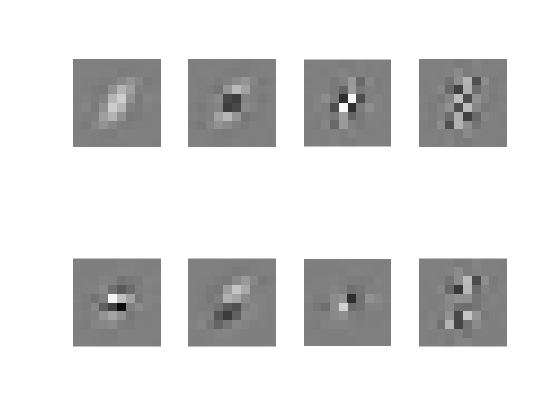

% Parameters for NSOLT
nLevels = 4;     % # of wavelet tree levels
nDecs   = [2 2]; % Decimation factor
nChs    = [4 4]; % # of channels
nOrds   = [4 4]; % Polyphase order
nVm     = 1;     % # of vanishing moments

% Location which containts a pre-designed NSOLT
sdir = './examples/quickdesign/results';

% Load a pre-designed dictionary from a MAT-file
%%{
s = load(sprintf('%s/nsolt_d%dx%d_c%d+%d_o%d+%d_v%d_l%d_n%d_%s.mat',...
    sdir,nDecs(1),nDecs(2),nChs(1),nChs(2),nOrds(1),nOrds(2),nVm,nLevels,...
    2048,'peppers128x128'),'nsolt');
%%}
%{
virLvTrn = 1;
s = load(sprintf('%s/nsolt_d%dx%d_c%d+%d_o%d+%d_v%d_vl%d_vn%d_%s_sgd.mat',...
    sdir,...
    nDecs(1),nDecs(2),nChs(1),nChs(2),...
    nOrds(1),nOrds(2),nVm,virLvTrn,...
    2048,'peppers128x128'),'nsolt');
%}
nsolt = s.nsolt; % saivdr.dictionary.nsolt.OvsdLpPuFb2dTypeIVm1System

% Conversion of nsolt to new package style
% nsolt = saivdr.dictionary.utility.fcn_upgrade(nsolt); 

% Show the atomic images by using a method atmimshow()
hfig1 = figure(1);
nsolt.atmimshow()
hfig1.Name = 'Atomic images of NSOLT';

## Create an analysis and synthesis system object

Since the object of OvsdLpPuFb2dTypeIVm1System, *nsolt* , is not able to process images by itself, we have to construct an analysis and synthesis system for analyzing and synthesizing an image, respectively. The following two systems can do these tasks:

- saivdr.dictionary.generalfb.Synthesis2dSystem

- saivdr.dictionary.generalfb.Analysis2dSystem

import saivdr.dictionary.generalfb.Analysis2dSystem
import saivdr.dictionary.generalfb.Synthesis2dSystem

% Change the output mode of NSOLT to 'AnalysisFilters' and
% draw inpulse responses of the analysis filters.
nsolt.release()
nsolt.OutputMode = 'AnalysisFilters';
analysisFilters = nsolt.step([],[]);

% Change the output mode of NSOLT to 'SynthesisFilters' and
% draw inpulse responses of the synthesis filters.
nsolt.release()
nsolt.OutputMode = 'SynthesisFilters';
synthesisFilters = nsolt.step([],[]);

% Create analysis ans synthesis system objects with
% frequency domain filtering mode.
analyzer    = Analysis2dSystem(...
    'DecimationFactor', nDecs,...
    'AnalysisFilters',  analysisFilters,...
    'NumberOfLevels',   nLevels,...
    'FilterDomain','Frequency');
analyzer.UseGpu = false;
synthesizer = Synthesis2dSystem(...
    'DecimationFactor',nDecs,...
    'SynthesisFilters',synthesisFilters,...
    'FilterDomain','Frequency');
synthesizer.setFrameBound(1);
synthesizer.UseGpu = false;

The following static factory methods can also be used to create lattice-based analysis and synthesis systems:

- saivdr.dictionary.nsoltx.NsoltFactory.createSynthesis2dSystem()

- saivdr.dictionary.nsoltx.NsoltFactory.createAnalysis2dSystem()

An available implementation is illustrated below. 

## Create an ISTA-based image restoration system object

Let the $\ell_1$-norm of $\mathbf{y}$, i.e. $\|\mathbf{y}\|_1$, be the sparsity measure of the coefficients. Then, the debluring problem can be formulated as 

$\hat{\mathbf{y}} = \arg\min_{\mathbf{y}}\frac{1}{2}\|\mathbf{x}-\mathbf{PDy}\|_2^2+\lambda\|\mathbf{y}\|_1$.

Provided that the blur process $\mathbf{P}$ is known and given as a linear process, the iterative shrinkage/thresholding algorithm (ISTA) becomes applicable to solve the above problem. In  **SaivDr Package**, image restoration with ISTA is implemented in the following class:

- saivdr.restoration.ista.IstaImRestoration

% Instantiation of ISTA system object
import saivdr.restoration.ista.IstaImRestoration2d
lambda    = 0.00185;                      % lambda
ista = IstaImRestoration2d(...
    'Synthesizer',        synthesizer,... % Synthesizer (Dictionary)
    'AdjOfSynthesizer',   analyzer,...    % Analyzer (Adj. of dictionary)
    'LinearProcess',      blur,...        % Blur process
    'Lambda',             lambda);        % Parameter lambda
ista.Eps0 = 1e-6;

## Create a step monitor system object

ISTA iteratively approaches to the optimum solution. In order to observe the intermediate results, the following class can be used:

- saivdr.utility.StepMonitoringSystem

% Parameters for StepMonitoringSystem
isverbose = true;  % Verbose mode
isvisible = true;  % Monitor intermediate results
hfig2 = figure(2); % Figure to show the source, observed and result image 
hfig2.Name = 'ISTA-based Image Restoration';

% Instantiation of StepMonitoringSystem
import saivdr.utility.StepMonitoringSystem
stepmonitor = StepMonitoringSystem(...
    'DataType', 'Image',...
    'SourceImage',   orgImg,...    % Original image
    'ObservedImage', obsImg,...    % Observed image
    'IsMSE',         false,...     % Switch for MSE  evaluation
    'IsPSNR',        true,...      % Switch for PSNR evaluation
    'IsSSIM',        false,...     % Switch for SSIM evaluation
    'IsVerbose',     isverbose,... % Switch for verbose mode
    'IsVisible',     isvisible,... % Switch for display intermediate result
    'ImageFigureHandle',hfig2);    % Figure handle
    
% Set the object to the ISTA system object
ista.StepMonitor = stepmonitor;

## Perform ISTA-based image restoration

STEP method of IstaImRestoration system object, *ista* , executes the ISTA-based image restoration to deblur the observed image. As the result, a restored image 


$$\hat{\mathbf{u}} = \mathbf{D}\hat{\mathbf{y}}$$


is obtained.

fprintf('\n ISTA')


 ISTA

(   1)  PSNR =  27.20 [dB] 
(   2)  PSNR =  27.94 [dB] 
(   3)  PSNR =  28.38 [dB] 
(   4)  PSNR =  28.68 [dB] 
(   5)  PSNR =  28.91 [dB] 
(   6)  PSNR =  29.08 [dB] 
(   7)  PSNR =  29.21 [dB] 
(   8)  PSNR =  29.33 [dB] 
(   9)  PSNR =  29.42 [dB] 
(  10)  PSNR =  29.50 [dB] 
(  11)  PSNR =  29.56 [dB] 
(  12)  PSNR =  29.62 [dB] 
(  13)  PSNR =  29.67 [dB] 
(  14)  PSNR =  29.72 [dB] 
(  15)  PSNR =  29.76 [dB] 
(  16)  PSNR =  29.80 [dB] 
(  17)  PSNR =  29.83 [dB] 
(  18)  PSNR =  29.85 [dB] 
(  19)  PSNR =  29.88 [dB] 
(  20)  PSNR =  29.90 [dB] 
(  21)  PSNR =  29.93 [dB] 
(  22)  PSNR =  29.94 [dB] 
(  23)  PSNR =  29.96 [dB] 
(  24)  PSNR =  29.98 [dB] 
(  25)  PSNR =  29.99 [dB] 
(  26)  PSNR =  30.01 [dB] 
(  27)  PSNR =  30.02 [dB] 
(  28)  PSNR =  30.03 [dB] 
(  29)  PSNR =  30.04 [dB] 
(  30)  PSNR =  30.05 [dB] 
(  31)  PSNR =  30.06 [dB] 
(  32)  PSNR =  30.07 [dB] 
(  33)  PSNR =  30.08 [dB] 
(  34)  PSNR =  30.09 [dB] 
(  35)  PSNR =  30.09 [dB] 
(  36)  PSNR =  30.1

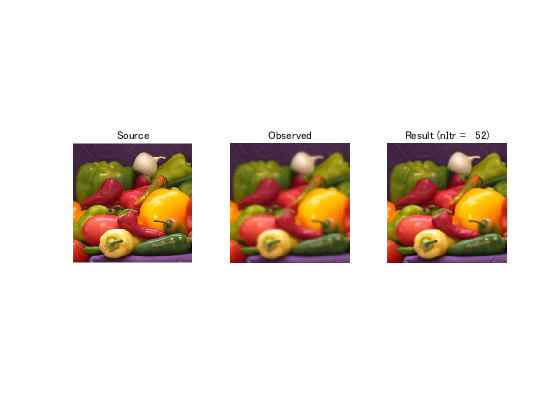

resImg = ista.step(obsImg); % STEP method of IstaImRestoration

## Extract the final evaluation

The object of StepMonitoringSystem, *stepmonitor* , stores the evaluation values calculated iteratively in ISTA as a vector. The GET method of *stepmonitor* can be used to extract the number of iterations and the sequence of PSNRs. 

nItr  = stepmonitor.nItr;
psnrs = stepmonitor.PSNRs;
psnr_ista = psnrs(nItr);

## Perform Wiener filtering

As a reference, let us show a result of Wiener filter.

% Create a step monitor system object for the PSNR evaluation
stepmonitor = StepMonitoringSystem(...
    'SourceImage',orgImg,...
    'MaxIter', 1,...
    'IsMSE',  false,...
    'IsPSNR', true,...
    'IsSSIM', false,...
    'IsVisible', false,...
    'IsVerbose', isverbose);

% Use the same blur kernel as that applied to the observed image, obsImg
blurKernel = blur.BlurKernel;

% Estimation of noise to signal ratio
nsr = noise_var/var(orgImg(:));

% Wiener filter deconvolution of Image Processing Toolbox
wnfImg = deconvwnr(obsImg, blurKernel, nsr);

% Evaluation
fprintf('\n Wiener')


 Wiener

psnr_wfdc = stepmonitor.step(wnfImg); % STEP method of StepMonitoringSystem

(   1)  PSNR =  25.52 [dB] 


## Compare deblurring performances

In order to compare the deblurring performances between two methods, ISTA-based deblurring with NSOLT and Wiener filter, let us show the original, observed and two results in one figure together.

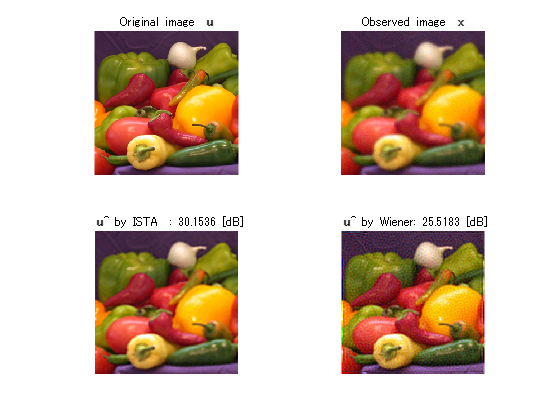

hfig3 = figure(3);

% Original image x
subplot(2,2,1)
imshow(orgImg)
title('Original image {\bf u}')

% Observed image u
subplot(2,2,2)
imshow(obsImg)
title('Observed image {\bf x}')

% Result u^ of ISTA 
subplot(2,2,3)
imshow(resImg)
title(['{\bf u}\^ by ISTA  : ' num2str(psnr_ista) ' [dB]'])

% Result u^ of Wiener filter
subplot(2,2,4)
imshow(wnfImg)
title(['{\bf u}\^ by Wiener: ' num2str(psnr_wfdc) ' [dB]'])

## Release notes

RELEASENOTES.txt contains release notes on **SaivDr Package**.

type('RELEASENOTES.txt')

* Release notes on Sparsity-Aware Image and Volumetric Data Restoration Package

- SaivDr20210924
-- (Minor) Revised to switch implicit expansion codes
--- saidr.dcnn.mexsrcs.*
-- (Minor) Excluded MEX code generation for GPU device (Due to a defect) 
--- mybuild.m

- SaivDr20210627
-- (Minor) Revised GPU implementation
--- saivdr.dcnn.nsoltBlockDct2dLayer
--- saivdr.dcnn.nsoltBlockIdct2dLayer
--- saivdr.dcnn.nsoltBlockDct3dLayer
--- saivdr.dcnn.nsoltBlockIdct2dLayer
-- (Minor) Revised code generation when no GPU device is available
--- saivdr.dcnn.mexsrcs.*
-- (Minor) Revised to avoid erros when no GPU device is available
--- saivdrrestoration.AbstOlsOlaProcess

- SaivDr20210620
-- (Major) GPU Coder support in some modules
--- mybuild.m
--- saivdr.dcnn.mexsrcs
-- (Major) Added some PyTorch modules
--- appendix/torch_nsolt
--- examples/dcnn
-- (Minor) Added new sample codes
--- examples/dcnn/main_nsolt_diclrn_tree_rgb.mlx
--- examples/dcnn/main_nsolt_sisr_rgb.mlx

- SaivDr20200903
-- (M